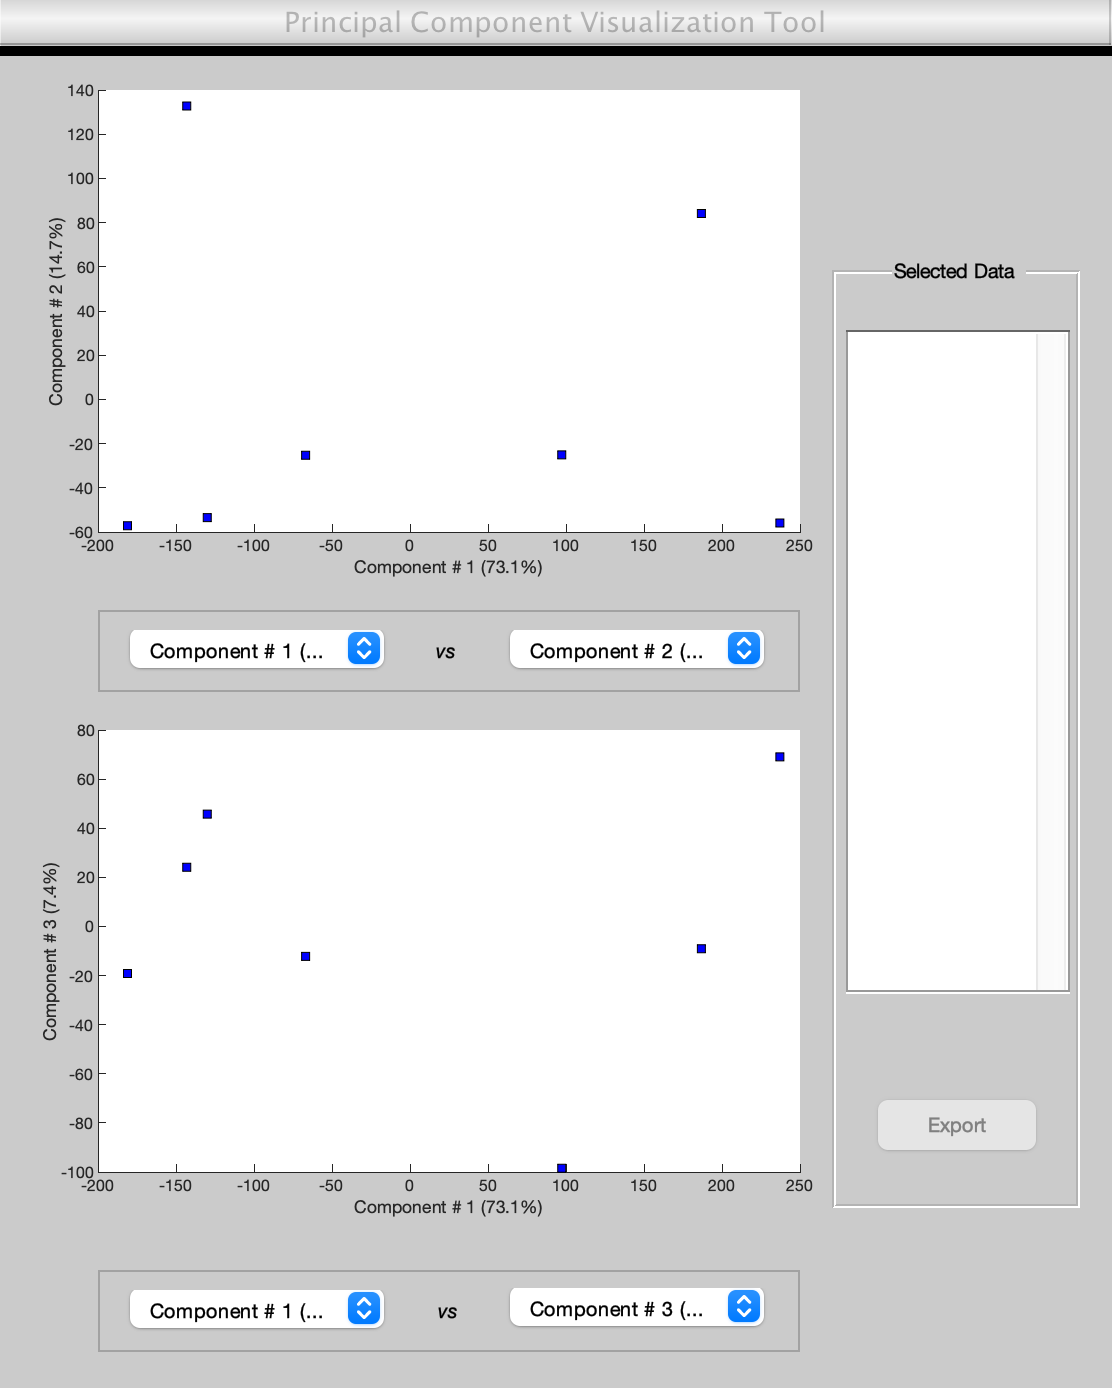

data= [180, 220, 40, 50, 80;
   100,  40, 60, 30, 20; 
   220, 220, 220, 20, 200;
   20, 0, 40, 33.33, 80;
   0, 0, 0, 0, 0;
   0, 30, 60, 200, 0;
   220, 220, 220, 100, 33.33];
grp= {'Sibling';'Sibling';'Sibling'; 'Mutant';'Mutant';'Mutant';'Mutant'};
mapcaplot(data);


figure();
pca_result=pca(data);


[coeff,score,latent,tsquared,explained,mu] = pca(data);

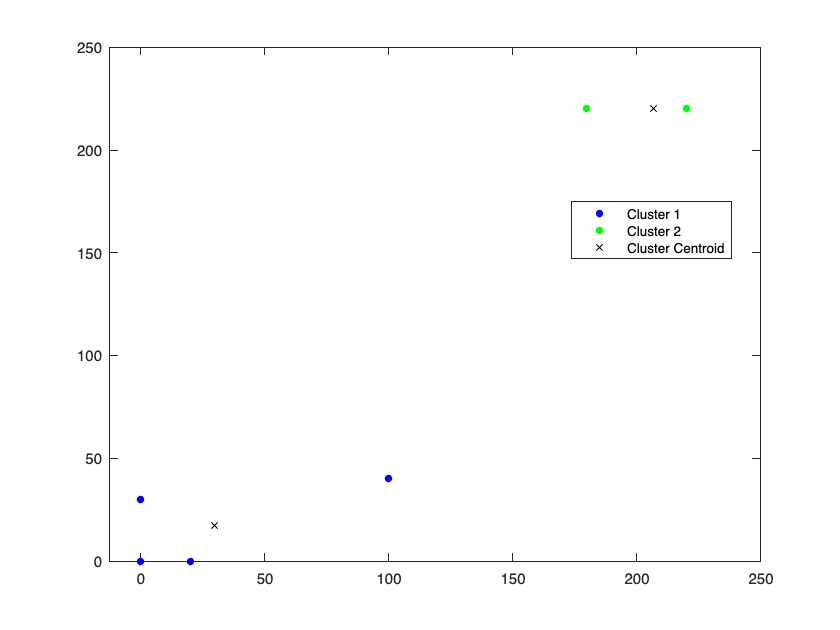

[idx,C,sumd,D] = kmeans(data, 2);
figure
gscatter(data(:,1),data(:,2),idx,'bgm')
hold on
plot(C(:,1),C(:,2),'kx')
legend('Cluster 1','Cluster 2','Cluster Centroid')

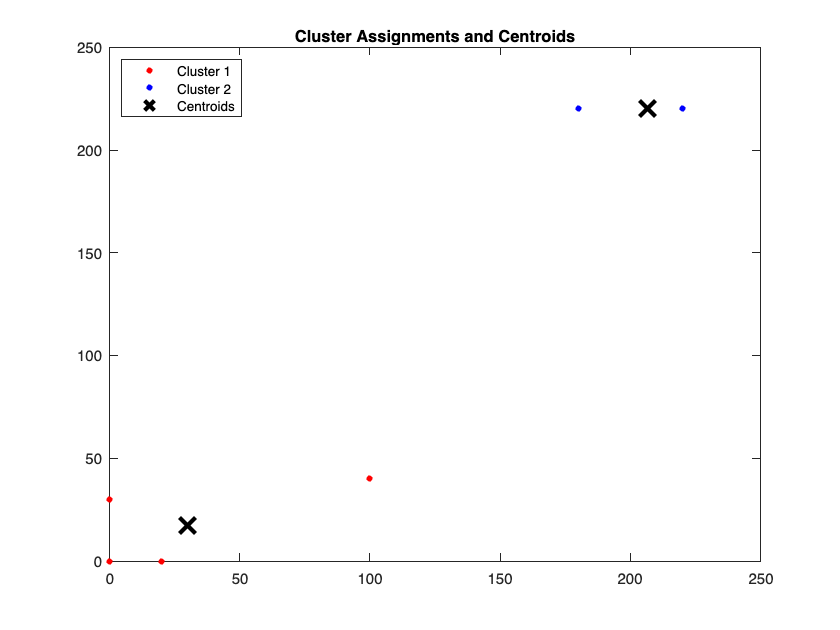

figure;
plot(data(idx==1,1),data(idx==1,2),'r.','MarkerSize',12)
hold on
plot(data(idx==2,1),data(idx==2,2),'b.','MarkerSize',12)
plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off